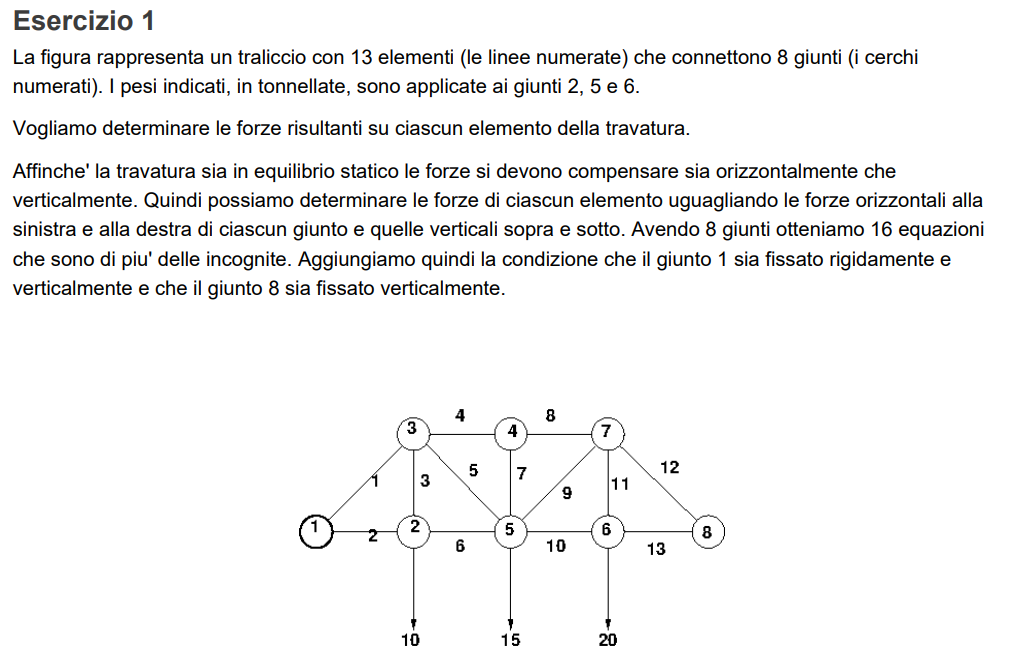

clear all
close all
a = 1/sqrt(2);
%   1  2  3  4  5  6  7  8  9 10 11 12 13
A =[0  1  0  0  0 -1  0  0  0  0  0  0  0;
    0  0  1  0  0  0  0  0  0  0  0  0  0;
    a  0  0 -1 -a  0  0  0  0  0  0  0  0;
    a  0  1  0  a  0  0  0  0  0  0  0  0;
    0  0  0  1  0  0  0 -1  0  0  0  0  0;
    0  0  0  0  0  0  1  0  0  0  0  0  0;
    0  0  0  0  a  1  0  0 -a -1  0  0  0;
    0  0  0  0  a  0  1  0  a  0  0  0  0;
    0  0  0  0  0  0  0  0  0  1  0  0 -1;
    0  0  0  0  0  0  0  0  0  0  1  0  0;
    0  0  0  0  0  0  0  1  a  0  0 -a  0;
    0  0  0  0  0  0  0  0  a  0  1  a  0;
    0  0  0  0  0  0  0  0  0  0  0  a  1];

b = [0 10 0 0 0 0 0 15 0 20 0 0 0];

Xapp =A\b'

Xapp =   -28.2843
   20.0000
   10.0000
  -30.0000
   14.1421
   20.0000
         0
  -30.0000
    7.0711
   25.0000


K = cond(A)

K = 10.4122

residui = b'-(A*Xapp);%vettore del residui 
norm(residui)

ans = 5.0243e-15

residuo = norm(residui)/norm(b)%per ottenere il residuo devo fare la norma del vettore rispetto al valore dei termini noti

residuo = 1.8660e-16

 

%con metodo lu
% [L,U]=lu(A);
% y = L\b'
% x = U\y

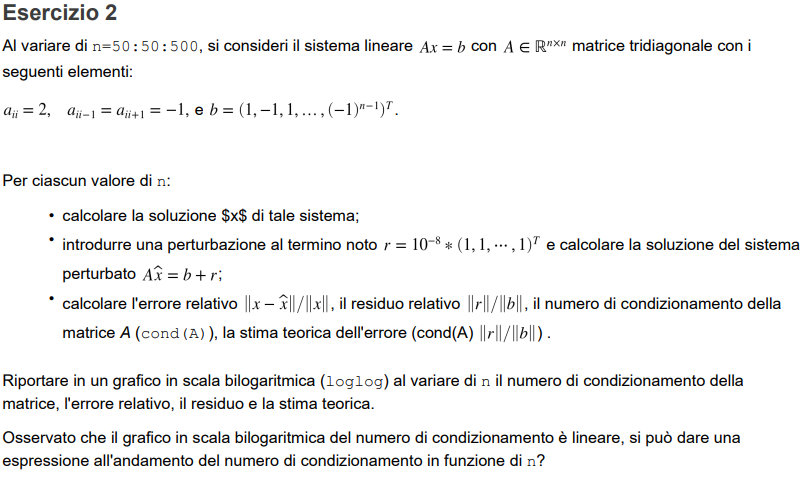

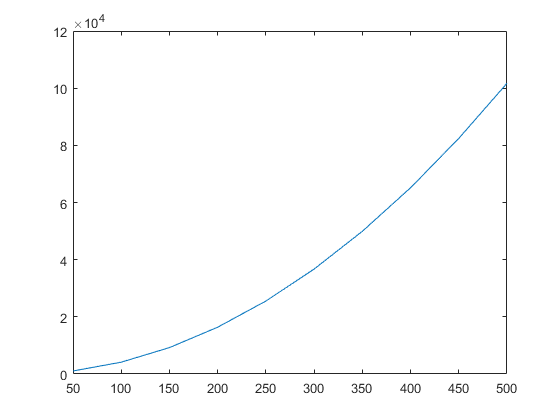

clear all
close all
err_rel = zeros(10,1);
K = zeros(10,1);
residui = zeros(10,1);
errore_stima = zeros(10,1); 
for n=50:50:500
    %eye matrice con diagonale di tutti 1
    %diag mette il vettore V nella diagonale sopra o sotto a quella
    %principale
    A = eye(n)*2 + diag(-ones(1,n-1),1) + diag(-ones(1,n-1),-1);
    b = ones(1,n);
    b(2:2:n)=-1;
    Xapp = A\b';
    
    r = 10^-8*ones(1,n);
    b_=b+r;
    x_=A\b_';
    residui(n/50) = norm(r)/norm(b);  
    err_rel(n/50) = norm(Xapp-x_)/norm(Xapp);
    K(n/50) = cond(A);  
    errore_stima(n/50) = K(n/50)*residui(n/50); 
end
n = 50:50:500;
plot(n,K)

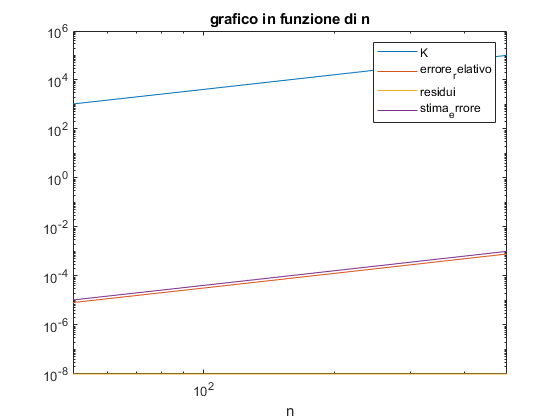

loglog(n,K,n,err_rel,n,residui,n,errore_stima)
title("grafico in funzione di n")
xlabel("n")
legend('K','errore_relativo','residui','stima_errore')

il numero di condizionamento aumenta in manira esponenziale in base al parametro N.